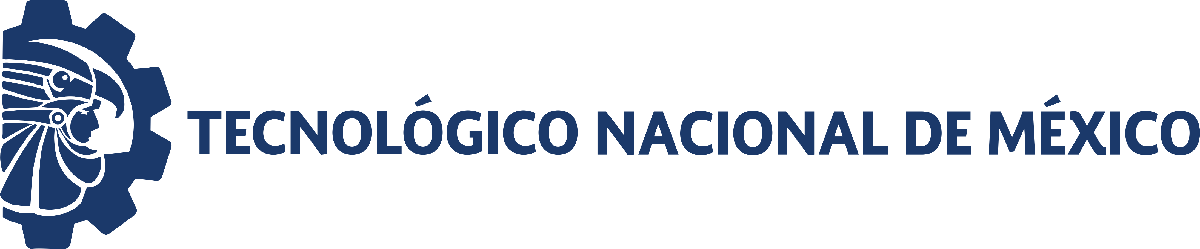                                 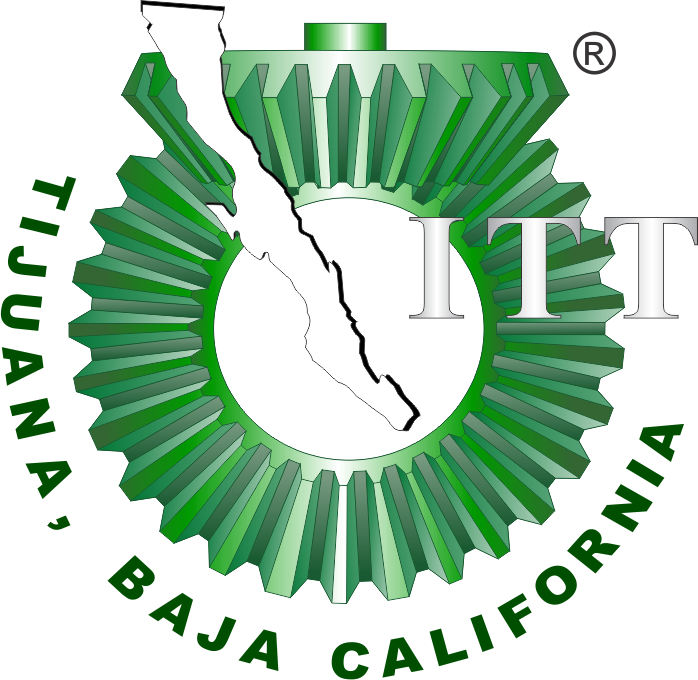

# Proyecto Final. Modelado Dinámico y Análisis de Convergencia de Modelos Biológicos.

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

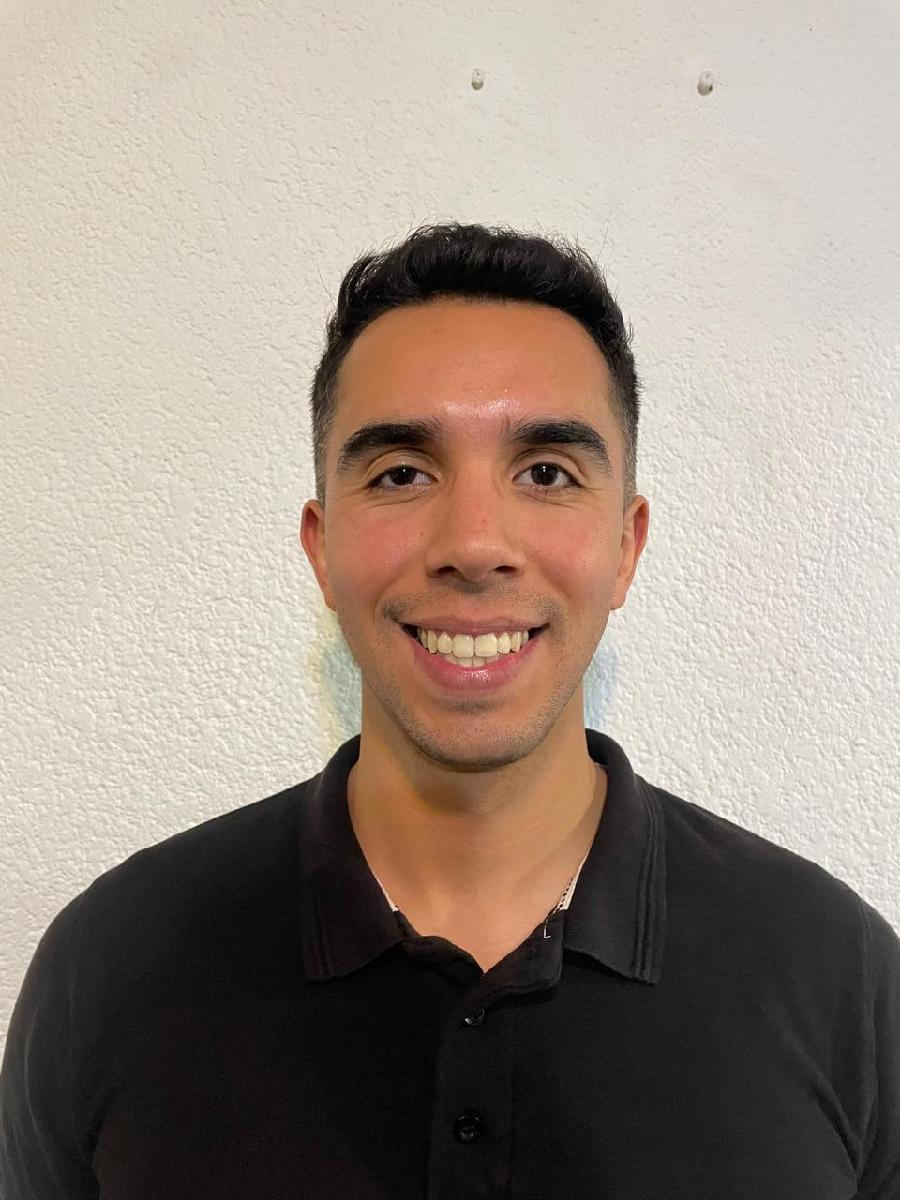

Nombre del alumno: **Carlos Andrés Gil Gárate**

Número de control: **21212743**

Correo institucional: **21212743@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## 1. Objetivo

Aplicar herramientas de modelado matemático y análisis computacional para representar y estudiar el comportamiento dinámico de un sistema biológico a partir de datos experimentales in vitro, mediante la suavización de señales, el ajuste de funciones exponenciales tipo 2T y la visualización de su convergencia en el tiempo, con el fin de validar la estabilidad local del sistema y caracterizar su tendencia asintótica hacia los puntos de equilibrio.

## 2. Adquisición y Preprocesamiento de Datos Experimentales 

### 2.1 Datos Experimentales 

clc; clear; close all; warning('off','all')
filename = 'data (5).csv';
sys = readmatrix(filename); 
t = round(sys(:,1));  
x1 = sys(:,2); y1 = sys(:,3); z1 = sys(:,4);
T = array2table([t, x1, y1, z1],'VariableNames', {'Tiempo', 'x1(t)', 'y1(t)', 'z1(t)',}); 
disp(T)

    Tiempo    x1(t)     y1(t)     z1(t) 
    ______    ______    ______    ______

       0       5.596      14.8    109.84
       7      11.975    12.135    100.18
      14      29.188     7.048    68.925
      21      48.982     3.126    29.523
      28       57.75     1.786     9.812
      35      60.279     1.431     4.976
      42      61.764     1.158     3.581
      49      62.522     0.881     3.064
      56      62.732     0.606      2.91
      63       62.91     0.321     2.804
      70      62.881     0.114      2.73



### 2.2 Grafica de datos experimentales (Raw data)

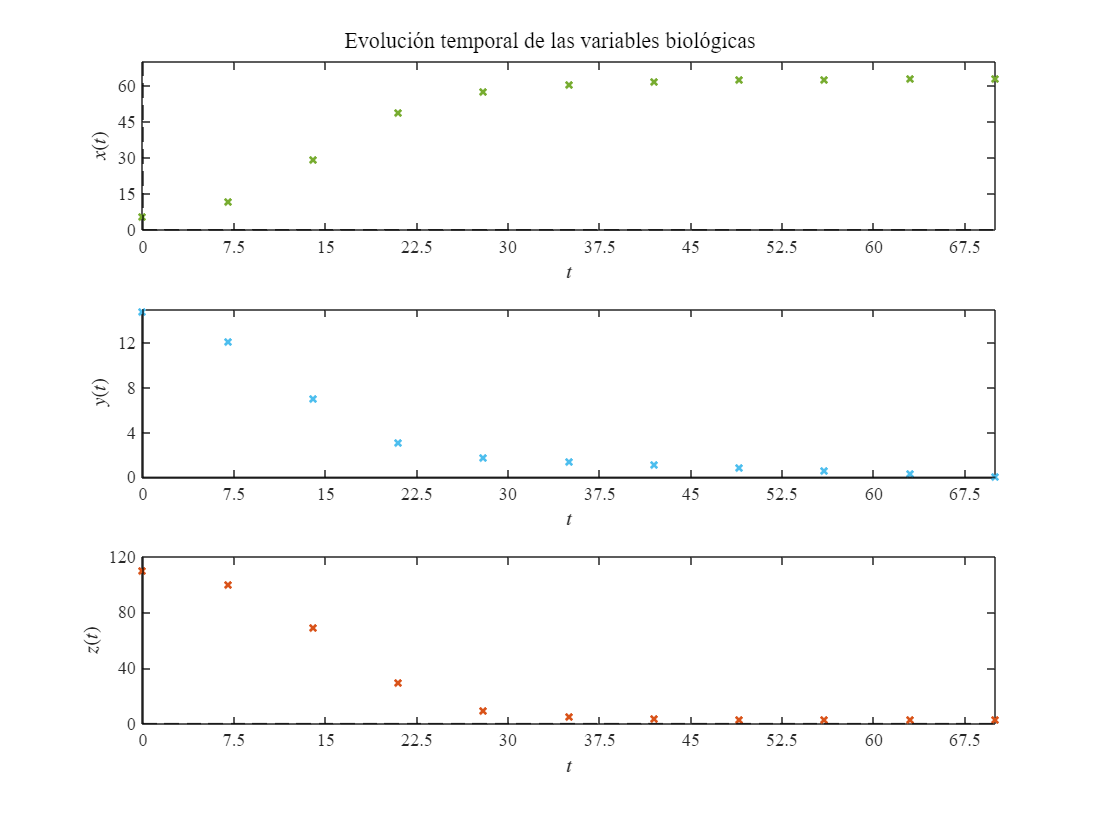

plotGraficas(t,x1,y1,z1) 

### 2.3 Datos Suavizados (Smooth Data)

sys = readmatrix(filename); 
t = sys(:,1);
x1 = sys(:,2);
y1 = sys(:,3);
z1 = sys(:,4);

xo =smoothdata(x1);
yo =smoothdata(y1);
zo =smoothdata(z1);

Ts = array2table([t, xo, yo, zo],'VariableNames', {'Tiempo', 'x_suave', 'y_suave', 'z_suave',});
disp(Ts)

    Tiempo    x_suave    y_suave    z_suave
    ______    _______    _______    _______

       0      8.7855      13.468    105.01 
       7      15.586      11.328     92.98 
      14      23.935      7.4363    77.116 
      21      36.974      3.9867    52.109 
      28       49.05      2.1143    28.309 
      35      57.194      1.4583    11.973 
      42      60.579      1.1567    5.3582 
      49      61.824     0.88167    3.6327 
      56      62.482     0.60267    3.0897 
      63      62.761       0.347     2.877 
      70      62.841      0.2175    2.8147 



writetable(Ts,'data_smooth.csv'); 

### 2.4 Grafica de Datos Suavizados

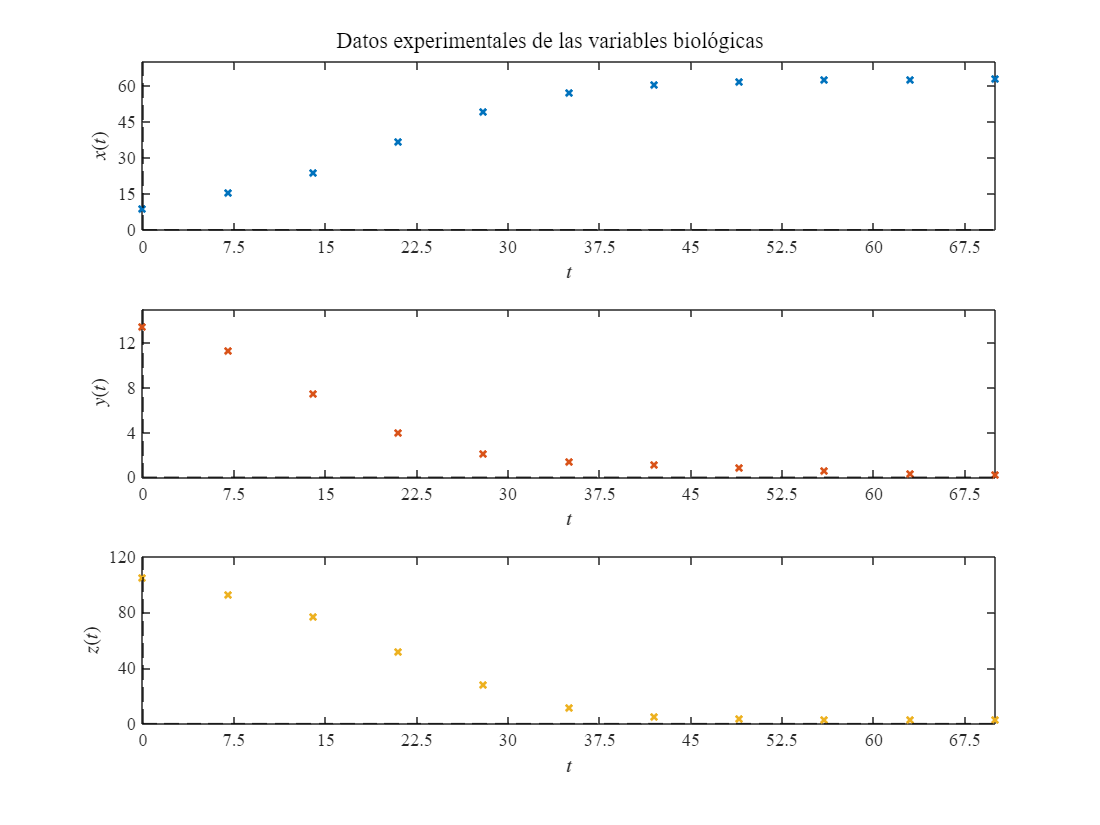

plotGraficas1(t,xo,yo,zo);

### 2.5 Modelo del Sistema 

### 2.6 Visualizacion de dinamica del sistema biológico (Biorender)

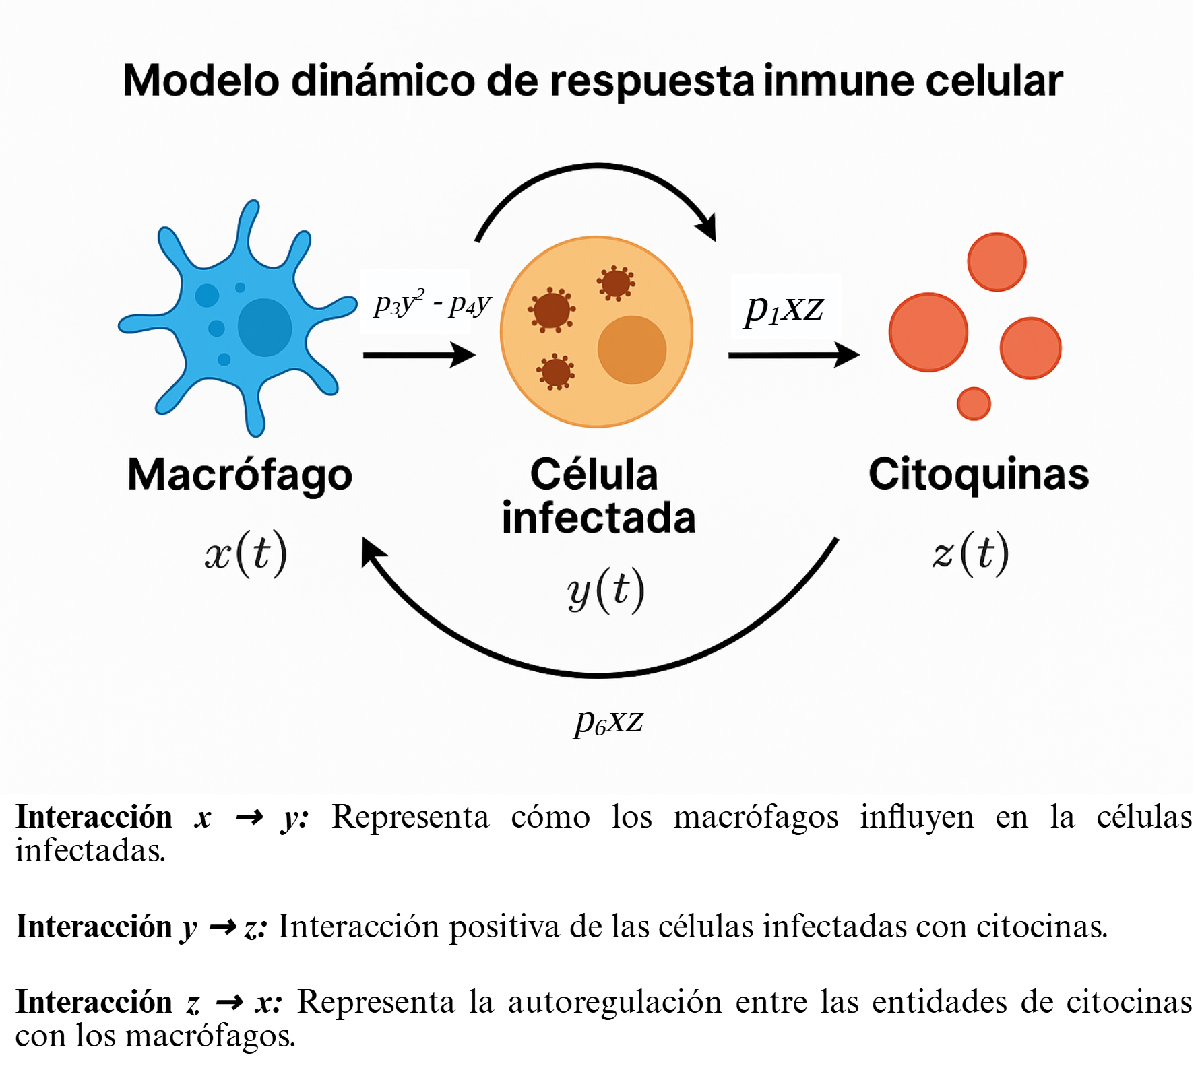

## 3. Algoritmo de Regresion No Lineal 

### 3.1 Datos de Regresion No Lineal 

P0 = [0.0010567, 0.0006, 0.00363, 0.07704, 0.0097, 0.00232];
[mdl, xa, ya, za ] = Model1 (t, xo, yo ,zo, P0); 


Sample size (n): 11
Parameters to be estimated (pars): 6
Degrees of freedom: 27
Significance level (alpha): 0.05
t-Student value: 2.0518
Adjusted R-squared: 0.99813
Corrected AIC (n/pars < 40): 121.499

    Parameters     Estimate         SE           MoE                  CI95                pvalue  
    __________    __________    __________    __________    ________________________    __________

      {'p1'}      0.00083882    1.7184e-05     3.526e-05    0.00080356    0.00087408    7.1031e-28
      {'p2'}      0.00059021    0.00073825     0.0015148    0.00092456      0.002105         0.431
      {'p3'}       0.0063883     0.0037043     0.0076006     0.0012124      0.013989      0.096042
      {'p4'}         0.11021      0.038284      0.078552      0.031661       0.18877     0.00771

### 3.2 Grafica de Regresion No Lineal 

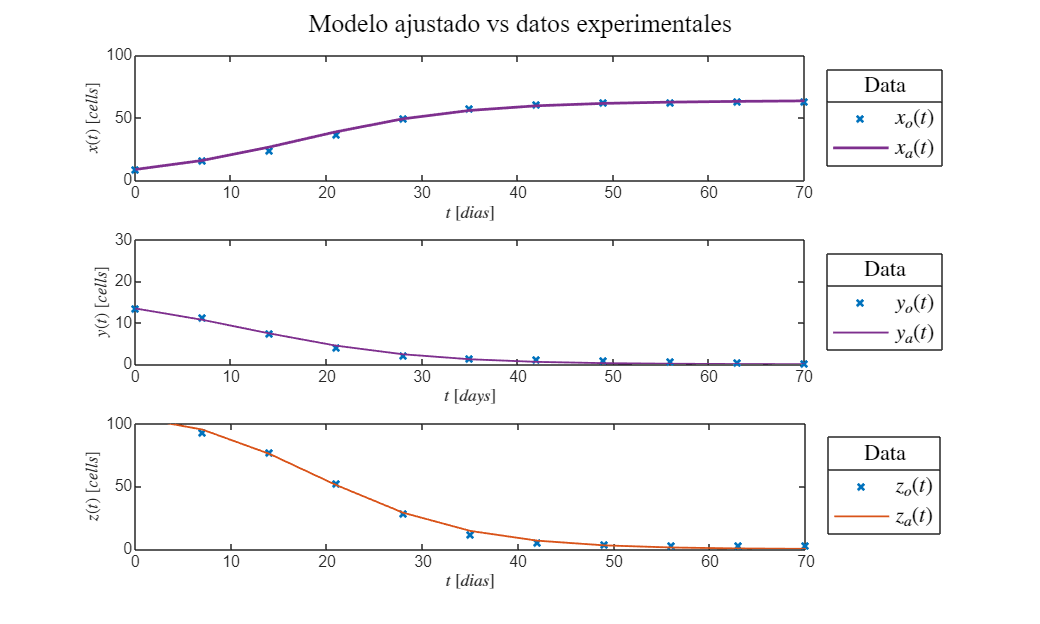

plotModel1(t,[xo,xa],[yo,ya],[zo,za]); 

## 4. Matriz Jacobiana 

%% Matriz Jacobiana
clear; clc
syms x y z p1 p2 p3 p4 p5 p6

% Definición del sistema
dx = p1*x*z + p2*x;
dy = p3*y^2 - p4*y;
dz = p5*z - p6*x*z;

% Matriz Jacobiana simbólica
J = jacobian([dx, dy, dz], [x, y, z]);
disp('Matriz Jacobiana simbólica del sistema:'); disp(J)

Matriz Jacobiana simbólica del sistema:


$$\left(\begin{array}{ccc} p_{2}+p_{1}\,z & 0 & p_{1}\,x\\ 0 & 2\,p_{3}\,y-p_{4} & 0\\ -p_{6}\,z & 0 & p_{5}-p_{6}\,x \end{array}\right)$$

% Parámetros ajustados
params = [p1, p2, p3, p4, p5, p6];
values = [0.00083882, 0.00059021, 0.0063883, 0.11021, 0.011358, 0.0020832];

### 4.1 Matriz Numérica

% Sustitución de parámetros numéricos
Jnum = subs(J, params, values);
disp('Matriz Jacobiana numérica (en función de x, y, z):'); disp(Jnum)

Matriz Jacobiana numérica (en función de x, y, z):


$$\left(\begin{array}{ccc} \frac{7736748931954523\,z}{9223372036854775808}+\frac{5443726409872057}{9223372036854775808} & 0 & \frac{7736748931954523\,x}{9223372036854775808}\\ 0 & \frac{7365208447879921\,y}{576460752303423488}-\frac{11021}{100000} & 0\\ -\frac{4803532156793967\,z}{2305843009213693952} & 0 & \frac{1636860306165571}{144115188075855872}-\frac{4803532156793967\,x}{2305843009213693952} \end{array}\right)$$

% Evaluación en el punto de equilibrio (0, 0, 0)
Jeval_num = subs(Jnum, {x, y, z}, {0, 0, 0});
Jeval_num = double(Jeval_num);

% Limpieza de la matriz para evitar valores muy pequeños no significativos
Jeval_num(abs(Jeval_num) < 1e-6) = 0;

### 4.2 Puntos de equilibrio

fprintf('\nMatriz Jacobiana evaluada en el punto (0, 0, 0):\n'); disp(Jeval_num);


Matriz Jacobiana evaluada en el punto (0, 0, 0):
    0.0006         0         0
         0   -0.1102         0
         0         0    0.0114



fprintf('\nValores propios (eigenvalores):\n'); disp(round(eig(Jeval_num), 6));


Valores propios (eigenvalores):
   -0.1102
    0.0006
    0.0114



## 5. Estabilidad Local 

clc; clear; close all; warning('off','all')

% Parámetros ajustados
p1 = 0.00083882;
p2 = 0.00059021;
p3 = 0.0063883;
p4 = 0.11021;
p5 = 0.011358;
p6 = 0.0020832;

% Variables simbólicas
syms x y z

% Definición del sistema
dx = p1*x*z + p2*x;
dy = p3*y^2 - p4*y;
dz = p5*z - p6*x*z;

% Resolución de puntos de equilibrio simbólicos
edos = solve([dx == 0, dy == 0, dz == 0], [x, y, z], 'Real', true);

% Extraer soluciones reales (si hay)
xe = double(edos.x);
ye = double(edos.y);
ze = double(edos.z);

% Filtrar resultados válidos (eliminar NaN)
idx_validos = ~(isnan(xe) | isnan(ye) | isnan(ze));
xe = xe(idx_validos);
ye = ye(idx_validos);
ze = ze(idx_validos);

% Tabla de puntos de equilibrio
n = length(xe);
nombres = cell(n,1);
for i = 1:n
    nombres{i} = sprintf('(x%d,y%d,z%d)',i,i,i);
end
Equilibria = table(xe, ye, ze, 'RowNames', nombres);
Equilibria.Properties.VariableNames = {'x*','y*','z*'};

fprintf('\nPuntos de equilibrio del sistema ajustado:\n'); disp(Equilibria)


Puntos de equilibrio del sistema ajustado:
                    x*        y*         z*   
                  ______    ______    ________

    (x1,y1,z1)         0         0           0
    (x2,y2,z2)    5.4522    17.252    -0.70362
    (x3,y3,z3)         0    17.252           0
    (x4,y4,z4)    5.4522         0    -0.70362



% Evaluación de la estabilidad (eigenvalores de la matriz Jacobiana)
L = zeros(n,3);
for i = 1:n
     J = [ (p1*ze(i) + p2),     0,         (p1*xe(i));
           0,         (2*p3*ye(i) - p4),     0;
           -p6*ze(i),      0,      (p5 - p6*xe(i)) ];
     L(i,:) = eig(J);
end

% Mostrar eigenvalores
L1 = L(:,1); L2 = L(:,2); L3 = L(:,3);
Lambdas = table(L1, L2, L3, 'RowNames', nombres);
Lambdas.Properties.VariableNames = {'λ₁', 'λ₂', 'λ₃'}; % Usa nombres más claros si gustas

fprintf('\nEigenvalores de la Jacobiana evaluada en cada punto de equilibrio:\n'); disp(Lambdas)


Eigenvalores de la Jacobiana evaluada en cada punto de equilibrio:
                      λ₁            λ₂           λ₃   
                  __________    __________    ________

    (x1,y1,z1)      -0.11021    0.00059021    0.011358
    (x2,y2,z2)     0.0025891    -0.0025891     0.11021
    (x3,y3,z3)    0.00059021      0.011358     0.11021
    (x4,y4,z4)     0.0025891    -0.0025891    -0.11021



## 6. Predicción Exponencial a 2t

filename = 'data (5).csv';
sys = readmatrix(filename); 
t = sys(:,1);
x1 = sys(:,2);
y1 = sys(:,3);
z1 = sys(:,4);

% Suavizar señales
xo = smoothdata(x1);
yo = smoothdata(y1);
zo = smoothdata(z1);

% Valores iniciales y finales
x0 = xo(1);     x_inf = xo(end);     kx = 0.06;
y0 = yo(1);     y_inf = yo(end);     ky = 0.07;
z0 = zo(1);     z_inf = zo(end);     kz = 0.03;
t_ext = 0:1:200;

% Calcular modelos con tiempo extendido
x_model = x_inf + (x0 - x_inf) * exp(-kx * t_ext);
y_model = y_inf + (y0 - y_inf) * exp(-ky * t_ext);
z_model = z_inf + (z0 - z_inf) * exp(-kz * t_ext);
t_ext = 0:1:200;

### 6.1 Grafica de ajuste a 2t

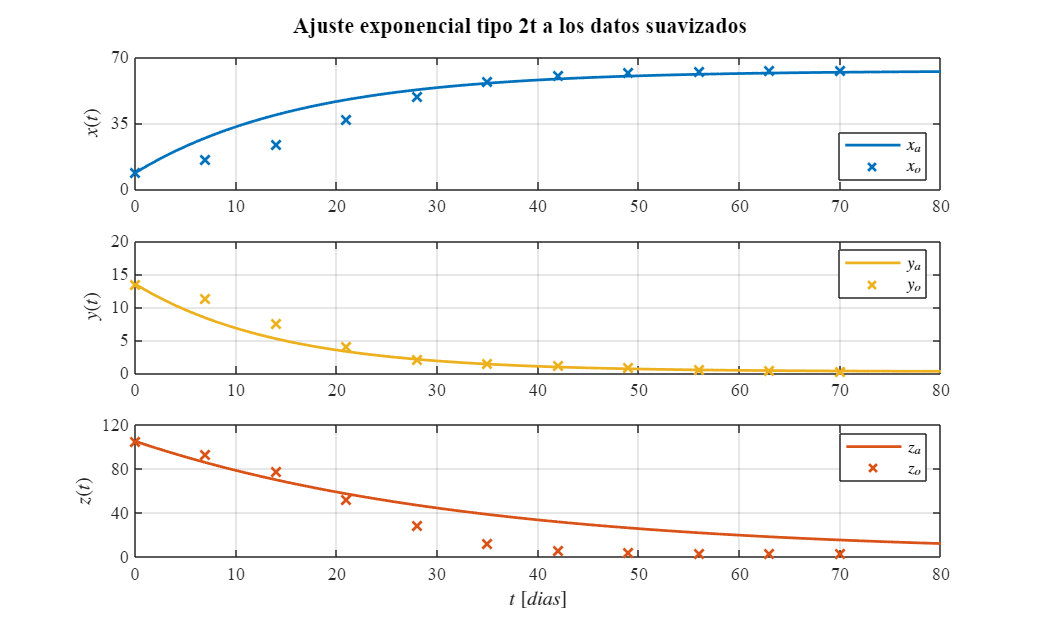

graficarAjuste2t(t_ext, t, xo, yo, zo, x_model, y_model, z_model)

## 7. Conclusión 

La presente práctica permitió implementar de forma integral los conceptos fundamentales de los gemelos digitales aplicados a un sistema fisiológico con datos experimentales. A través del procesamiento, suavizado y análisis de señales biológicas, fue posible construir un modelo matemático basado en ecuaciones diferenciales que describe la dinámica temporal de tres variables biológicas clave. Mediante técnicas de regresión no lineal, se estimaron los parámetros que mejor ajustan el modelo a los datos observados, validando su comportamiento mediante simulaciones, gráficas comparativas y análisis de estabilidad. 

A lo largo de la materia, se fortalecieron habilidades esenciales como el modelado computacional, el análisis dinámico, la identificación de sistemas y la visualización avanzada de datos. Del mismo modo, se comprendió el potencial de los gemelos digitales como herramienta para representar, predecir y controlar sistemas biológicos en tiempo real, sentando las bases para aplicaciones futuras en monitoreo clínico, investigación biomédica y personalización de tratamientos. En conjunto, esta experiencia académica integró teoría, simulación y análisis crítico, fomentando un enfoque interdisciplinario que refleja la esencia de la Ingeniería Biomédica moderna.

## 8. Funciones de Práctica

### 8.1 Grafica de Datos Experimentales (Raw Data)

function plotGraficas(t, x1, y1, z1)
    % Crear figura
    fig = figure('Position', [100, 100, 800, 600]);  
    rd = [0.6350 0.0780 0.1840];
    cy = [0.3010 0.7450 0.9330];
    gr = [0.4660 0.6740 0.1880];
    pr = [0.4940 0.1840 0.5560];
    or = [0.8500 0.3250 0.0980];

    % Subplot 1: x(t)
    subplot(3,1,1)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, x1, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', gr)
    xlabel('$t$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 70]); yticks(0:15:70)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    % Subplot 2: y(t)
    subplot(3,1,2)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, y1, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', cy)
    xlabel('$t$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 15]); yticks(0:4:15)
    xline(0,'','LineWidth',1,'Color','k')
    yline(0,'','LineWidth',1,'Color','k')

    % Subplot 3: z(t)
    subplot(3,1,3)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, z1, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', or)
    xlabel('$t$','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 120]); yticks(0:40:120)
    xline(0,'','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    % Título general de la figura
    sgtitle('Evolución temporal de las variables biológicas','FontName','Times New Roman','FontSize',12)

    % Exportar la figura a PDF
    exportgraphics(fig, 'grafica_trayectorias.pdf', 'ContentType', 'vector');
end

### 8.2 Grafica de Datos Suavizados

function plotGraficas1(t, xo, yo, zo)
    % Crear figura
    fig = figure('Position', [100, 100, 800, 600]);  

    % Definición de colores
    blu = [0 0.4470 0.7410];      % Azul
    nrj = [0.8500 0.3250 0.0980]; % Naranja
    amr = [0.9290 0.6940 0.1250]; % Amarillo

    % Subplot 1: x(t)
    subplot(3,1,1)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, xo, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', blu)
    xlabel('$t$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 70]); yticks(0:15:70)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    % Subplot 2: y(t)
    subplot(3,1,2)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, yo, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', nrj)
    xlabel('$t$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 15]); yticks(0:4:15)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    % Subplot 3: z(t)
    subplot(3,1,3)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, zo, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', amr)
    xlabel('$t$','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 120]); yticks(0:40:120)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    % Título general
    sgtitle('Datos experimentales de las variables biológicas','FontName','Times New Roman','FontSize',12)

    % Exportar a PDF
    exportgraphics(fig, 'grafica_datos_experimentales.pdf', 'ContentType', 'vector');
end

### 8.3 Regresión No Lineal

function plotModel1(t, x, y, z)
    % Crear figura y configurar dimensiones
    fig = figure('Color','w');
    set(fig, 'Units','Centimeters','Position',[2, 2, 20, 12]);
    set(gca, 'FontName','Times New Roman');
    fontsize(12, 'points');

    % Colores
    blu = [0 0.4470 0.7410];      % Azul
    mor = [0.4940 0.1840 0.5560]; % Morado
    naj = [0.8500 0.3250 0.0980]; % Naranja

    % Subplot 1: x(t)
    subplot(3,1,1)
    hold on; box on; grid off;
    plot(t, x(:,1), 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', blu)
    plot(t, x(:,2), '-', 'LineWidth',1.5, 'Color', mor)
    xlabel('$t$ $[dias]$', 'Interpreter','latex')
    ylabel('$x(t)$ $[cells]$', 'Interpreter','latex')
    L = legend('$x_o(t)$', '$x_a(t)$');
    set(L, 'Interpreter','latex', 'FontSize',12, 'Location','EastOutside', 'Box','on')
    title(L, 'Data')
    xlim([min(t) max(t)])
    ylim([0 100])

    % Subplot 2: y(t)
    subplot(3,1,2)
    hold on; box on; grid off;
    plot(t, y(:,1), 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', blu)
    plot(t, y(:,2), '-', 'LineWidth',1, 'Color', mor)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$y(t)$ $[cells]$', 'Interpreter','latex')
    L = legend('$y_o(t)$', '$y_a(t)$');
    set(L, 'Interpreter','latex', 'FontSize',12, 'Location','EastOutside', 'Box','on')
    title(L, 'Data')
    xlim([min(t) max(t)])
    ylim([0 30])

    % Subplot 3: z(t)
    subplot(3,1,3)
    hold on; box on; grid off;
    plot(t, z(:,1), 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', blu)
    plot(t, z(:,2), '-', 'LineWidth',1, 'Color', naj)
    xlabel('$t$ $[dias]$', 'Interpreter','latex')
    ylabel('$z(t)$ $[cells]$', 'Interpreter','latex')
    L = legend('$z_o(t)$', '$z_a(t)$');
    set(L, 'Interpreter','latex', 'FontSize',12, 'Location','EastOutside', 'Box','on')
    title(L, 'Data')
    xlim([min(t) max(t)])
    ylim([0 100])

    % Título general
    sgtitle('Modelo ajustado vs datos experimentales','FontName','Times New Roman','FontSize',14)

    % Exportar a PDF
    exportgraphics(fig, 'modelo_vs_ajuste.pdf', 'ContentType', 'vector');
end


### 8.4 Ajuste del Modelo Matemático (Fitting_model)

function [mdl, xa, ya, za] = Model1(to, xo, yo, zo, P0)
    % Valores iniciales
    x0 = xo(1); y0 = yo(1); z0 = zo(1);

    % Expande el vector tiempo para las 3 variables
    to = [to; to; to];

    % Observaciones reales concatenadas: x, y, z
    fo = [xo; yo; zo];

    % Modelo anidado para el ajuste
    function fi = model(p, t)
        dt = 1E-3;
        t = reshape(t, [], 3); % Redimensiona por seguridad
        t = t(:, 1);           % Solo usa la primera columna (tiempo original)
        time = (0:dt:max(t))'; % vector de tiempo para integración
        n = round(max(t)/dt);

        % Inicialización
        x = zeros(n+1, 1); x(1) = x0;
        y = zeros(n+1, 1); y(1) = y0;
        z = zeros(n+1, 1); z(1) = z0;

        % Simulación (Heun)
        for i = 1:n
            [fx, fy, fz] = f(x(i), y(i), z(i), p);
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn, fyn, fzn] = f(xn, yn, zn, p);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        % Interpolación para los puntos de medición
        xi = zeros(length(t), 1);
        yi = zeros(length(t), 1);
        zi = zeros(length(t), 1);

        for j = 1:length(t)
            [~, idx] = min(abs(time - t(j)));
            xi(j) = x(idx);
            yi(j) = y(idx);
            zi(j) = z(idx);
        end

        fi = [xi; yi; zi];  % Concatenar en columna
    end

    % Ecuaciones diferenciales 
    function [dx, dy, dz] = f(x, y, z, p)
        dx = p(1) * x * z + p(2) * x;  
        dy = p(3) * y^2 - p(4) * y;
        dz = p(5) * z - p(6) * x * z;
    end

    % Ajuste de regresión no lineal
    mdl = fitnlm(to, fo, @model, P0);

    % Resultados ajustados
    fa = mdl.Fitted;
    fn = reshape(fa, [], 3);
    xa = fn(:, 1); ya = fn(:, 2); za = fn(:, 3);

    % Reporte de coeficientes
    Estimate = table2array(mdl.Coefficients(:, 1));
    SE = table2array(mdl.Coefficients(:, 2));
    pvalue = table2array(mdl.Coefficients(:, 4));
    alpha = 0.05;
    CI95OG = coefCI(mdl, alpha);
    CI95 = abs(CI95OG);
    dof = mdl.DFE;
    tval = tinv(1 - alpha/2, dof);
    MoE = SE * tval;
    Parameters = {'p1'; 'p2'; 'p3'; 'p4'; 'p5'; 'p6'};
    Results = table(Parameters, Estimate, SE, MoE, CI95, pvalue);

    % Mostrar resumen
    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', ...
              num2str(mdl.ModelCriterion.AICc), '\n\n'])
    disp(Results)
end

### 8.5 Graficas a Escala 2t

function graficarAjuste2t(t_ext, t, xo, yo, zo, x_model, y_model, z_model)
    % Colores
    blu = [0 0.4470 0.7410];
    amr = [0.9290 0.6940 0.1250];
    nrj = [0.8500 0.3250 0.0980];

    % Crear figura
    fig = figure('Color','w', 'Units','centimeters', 'Position',[2,2,20,12]);

    % Subplot 1: x(t)
    subplot(3,1,1)
    plot(t_ext, x_model, '-', 'Color', blu, 'LineWidth', 1.5)
    hold on
    scatter(t, xo, 50, 'x', 'MarkerEdgeColor', blu, 'LineWidth', 1.5)
    ylabel('$x(t)$', 'Interpreter', 'latex')
    legend('$x_{a}$','$x_{o}$', 'Interpreter', 'latex', 'Location', 'best')
    xlim([0 80])
    ylim([0 70])
    yticks(0:35:70)
    grid on
    set(gca, 'FontName','Times New Roman', 'FontSize', 10)

    % Subplot 2: y(t)
    subplot(3,1,2)
    plot(t_ext, y_model, '-', 'Color', amr, 'LineWidth', 1.5)
    hold on
    scatter(t, yo, 50, 'x', 'MarkerEdgeColor', amr, 'LineWidth', 1.5)
    ylabel('$y(t)$', 'Interpreter', 'latex')
    legend('$y_{a}$','$y_{o}$', 'Interpreter', 'latex', 'Location', 'best')
    xlim([0 80])
    ylim([0 20])
    yticks(0:5:20)
    grid on
    set(gca, 'FontName','Times New Roman', 'FontSize', 10)

    % Subplot 3: z(t)
    subplot(3,1,3)
    plot(t_ext, z_model, '-', 'Color', nrj, 'LineWidth', 1.5)
    hold on
    scatter(t, zo, 50, 'x', 'MarkerEdgeColor', nrj, 'LineWidth', 1.5)
    ylabel('$z(t)$', 'Interpreter', 'latex')
    xlabel('$t$ $[dias]$', 'Interpreter', 'latex')
    legend('$z_{a}$','$z_{o}$', 'Interpreter', 'latex', 'Location', 'best')
    xlim([0 80])
    ylim([0 120])
    yticks(0:40:120)
    grid on
    set(gca, 'FontName','Times New Roman', 'FontSize', 10)

    % Título general
    sgtitle('Ajuste exponencial tipo 2t a los datos suavizados', ...
            'FontName','Times New Roman','FontSize',12, 'FontWeight', 'bold')

    % Exportar la figura a PDF
    exportgraphics(fig, 'ajuste_exponencial_2t.pdf', 'ContentType', 'vector');
end

## Referencias

[1]  Paul. A. Valle, Syllabus de Biomatemáticas para la asignatura de Gemelos Digitales, Tecnológico Nacional de México/IT Tijuana, Tijuana, B.C., México, 2025. Permalink: https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf

[2] Dominik Wordaz & Natalia L. Komarova, Dynamics of Cancer: Mathematical Foundations of Oncology, University of California, Irvine, USA, 2014.

[3] Robert A. Gatenby & Thomas L. Vincent, "Application of quantitative models from population biology and evolutionary game theory to tumor therapeutic strategies," Molecular Cancer Therapeutics, vol. 2, no. 9, pp. 919–927, Jun 2003.